# Homework 2

## Natalie Shen

clear all;
close all;
clc;

### 1)

The rolling sevens is more probability as there are more ways to get sevens than snake eyes. Snake eyes only happens on one instance, both die turn up 1. For sevens, there are three ways of getting seven, 1-6, 2-5 and 3-4. We can inverse them too as it doesn't matter which die gives the number per set, so we can include 6-1, 5-2 and 4-3, making for a total of six ways to get sevens. Since there are 36 possible combinations between two die (6 * 6 = 36), then the ratio for snake eyes is 1:36 and the ratio for sevens is 6:36 or 1:6.

### 2)

Sums:

2     

- 1+1

1/36

3

- 1+2

- 2+1

2/36 or 1/18

4

- 1+3

- 3+1

- 2+2

3/36 or 1/12

5

- 1+4

- 4+1

- 2+3

- 3+2

4/36 or 1/9

6

- 1+5

- 5+1

- 2+4

- 4+2

- 3+3

5/36

7

- 1+6

- 6+1

- 2+5

- 5+2

- 3+4

- 4+3

6/36 or 1/6

8

- 2+6

- 6+2

- 3+5

- 5+3

- 4+4

5/36

9

- 3+6

- 6+3

- 4+5

- 5+4

4/36 or 1/9

10

- 4+6

- 6+4

- 5+5

3/36 or 12

11

- 5+6

- 6+5

2/36 or 1/18

12

- 6+6

1/36

p = 6*6;
x = zeros(1,p);
count = 0;

for dice1 = 1:1:6
    sum = dice1;
    for dice2 = 1:1:6
        count = count + 1;
        sum = sum + dice2;
        x(count) = sum;
        sum = dice1;
    end
end
disp(x)

  Columns 1 through 23

     2     3     4     5     6     7     3     4     5     6     7     8     4     5     6     7     8     9     5     6     7     8     9

  Columns 24 through 36

    10     6     7     8     9    10    11     7     8     9    10    11    12



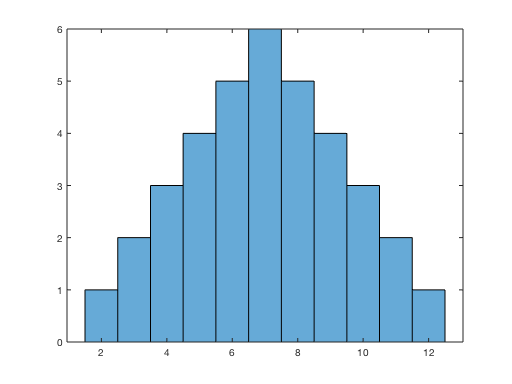

histogram(x)

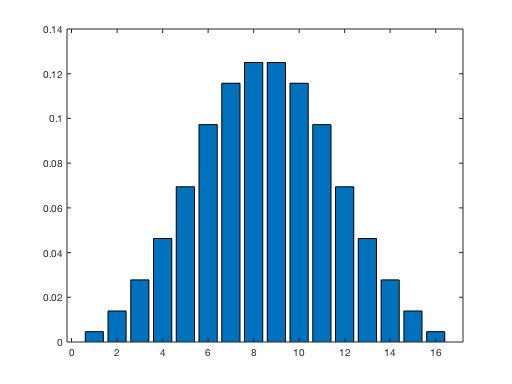


[N,edges] = histcounts(x);
y = zeros(1,length(N));
for r = 1:1:length(N)
    per = (N(r) / p);
    y(r) = per;
end

z = zeros(1,6);
for zc = 1:1:6
    z(zc) = 1/6;
end

b = conv(z,y,"full");
bar(b)

### 3)

%mean and variance of the sums
mean(x)

ans = 7

V = var(x)

V = 6

%mean and variance of the probabilities
mean(y)

ans = 0.0909

V = var(y)

V = 0.0022

### 4)

Doing a trial run of 10 dice being rolled at once. The trial is done a total of 100 times.

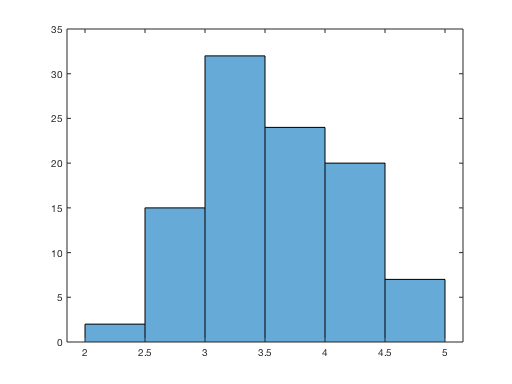

means = zeros(1,100);
for t = 1:1:100
    rolls = randi(6,10,1);
    means(t) = mean(rolls);
end

histogram(means)

mean(means)

ans = 3.5280

V = var(means)

V = 0.3612


[N,edges] = histcounts(means);
prob = zeros(1,length(N));
p = 6^100;
for t = 1:1:length(N)
    per = (N(t) / p);
    prob(t) = per;
end

compare = zeros(1,6);
for t = 1:1:6
    compare(t) = 1/6;
end
b = conv(compare,prob,"full")

b = 	1.0e+-76 *

    0.0051    0.0434    0.1250    0.1862    0.2373    0.2551    0.2500    0.2117    0.1301    0.0689    0.0179


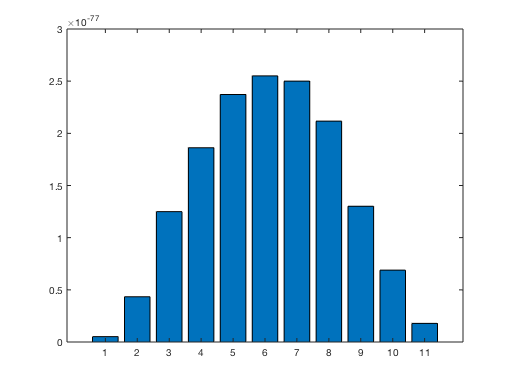

bar(b)

The bar graph shows the classic bell curve like that in a normal distribution (or guassian distribution), though not perfect, the similarities show that using teh convulution operator of the probabilities of the sum of n number of dice and the probabilityes of a regular die will result in a guassian distribution shape. So yes, this is more or less a guassian distribution.

### 5)

Using the bar graph made in problem 4

sum = 0;

sum = 0

for z = 1:1:length(b)
    sum = sum + b(z);
end
mean = mean(b)

mean = 1.3915e-77

sum

sum = 1.5306e-76